# Happy Birthday song (Full)

### Notes to the Birthday Song 

#### 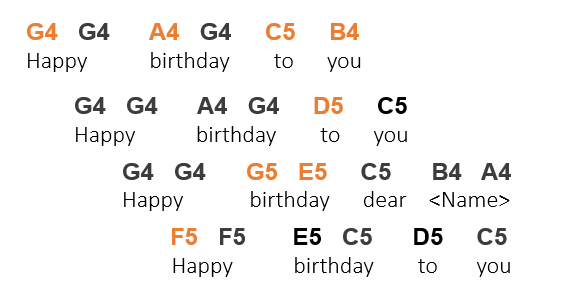

### Create one variable for each unique note (highlighted orange) to store its frequency

G4 = 392;
A4 = 440;
C5 = 523.3;
B4 = 493.9;
D5 = 587;
G5 = 784;
F5 = 698.5;
E5 = 659;

### Call sineSound() function to play the notes

http://www.pianobychords.com/chordsheet/happybirthday.txt

% First Line
sineSound(G4,0.5); %Ha
pause(0.5);
sineSound(G4,0.5);%ppy
pause(0.5);
sineSound(A4,1);%Bir
pause(1);
sineSound(G4,1);%thday
pause(1);
sineSound(C5,1);%to
pause(1);
sineSound(B4,2);%you
pause(2);

%Second Line
sineSound(G4,0.5);
pause(0.5);
sineSound(G4,0.5);
pause(0.5);
sineSound(A4,1);
pause(1);
sineSound(G4,1);
pause(1);
sineSound(D5,1);
pause(1);
sineSound(C5,2);
pause(2);

% Third Line
sineSound(G4,0.5);
pause(0.5);
sineSound(G4,0.5);
pause(0.5);
sineSound(G5,1);
pause(1);
sineSound(E5,1);
pause(1);
sineSound(C5,1);
pause(1);
sineSound(B4,1);
pause(1);
sineSound(A4,2);
pause(2);

% Fourth Line
sineSound(F5,0.5);
pause(0.5);
sineSound(F5,0.5);
pause(0.5);
sineSound(E5,1);
pause(1);
sineSound(C5,1);
pause(1);
sineSound(D5,1);
pause(1);
sineSound(C5,2);

**Helper Functions **(do not edit)

function varargout = sineSound(varargin)

    Fs = 8000; 
    Ts = 1/Fs;
    
if nargin == 1
    freq = round(varargin{1},3);
    time = 0.2 ; 
    amp = 1;
    
elseif nargin == 2
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = 1;
    
elseif nargin == 3
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = varargin{3};
   
end

t = 0:Ts:time;
pure_sine = sin(2*pi*freq*t); 
step = 1/(length(t)/2); 
len = 1;
sine_coefficient = [(sin((pi* [0:step:len/2.0]) / (len))) ...
                        ones(1, length([len/2.0:step:len*3/2]) - 2)...
                        abs(sin((pi* [len*3/2:step:len*2.0]) / (len)))]; %#ok<*NBRAK>

env = 0.5*amp.*pure_sine.*sine_coefficient;


if nargout == 1
    varargout{1} = env';
else 
    sound(env, Fs);
end
end

© COPYRIGHT 2024 by The MathWorks®, Inc.